clear
clc

## Variables

% Main Sim variables

Insulation_thickness=5; % mm
Air_thickness=1.5; % mm actually 1.46mm
Wall_thickness=5.5; % mm actually 5.49mm
Total_thickness=Insulation_thickness+Air_thickness+Wall_thickness;

dx=0.5;

Sim_time=15; % s
dt=0.001;

Tinf=3000;

% Conduction Variables/ Wall Material Variables

alpha_wall=4.2; % mm^2/s
alpha_insulation=10.5; % mm^2/s change
alpha_air=21; % mm^2/s change
c=0.5*1000; % J/(kg-K)
rho=8000/(1000^3); % kg/mm^3

% Vacuum Radiation Variables

emiss_insulation=0.8;
emiss_air=0.8;
emiss_steel=0.4;

boltz=5.67e-8/(1000^2); % J/(s-mm^2-K)

% Radiation from reaction products to insualtion variables

emiss_r_Tinf=0.2; % change this
emiss_g_Twall=0.4; % supposed to be steel or not?
emiss_e=emiss_insulation/(1-(1-emiss_insulation)*(1-emiss_r_Tinf));

% Bartz Method Variables

gamma=1.176;
T0c=3000;
M=0.0438; % changes with area
cstar=1095*1000; % mm/s changes with area

D_t=17.6; % mm
D_t=D_t/25.4; % inch
Pr=0.4939;
Pr0_inf=0.4939;
mu0_inf=9.691e-8; % kg/(mm-s)
mu0_inf=mu0_inf*55.9974; % lb/(inch-s)
Cp0_inf=3.3334*1000; % J/(kg-K)
Cp0_inf=Cp0_inf/4186.8; % BTU/(lb-Fahrenheit)
p0_c=(30*10^5)/6895; % lb/(inch)^2
cstar=cstar/25.4; % inch/s
R=13.2; % mm
R=R/25.4; % inch
At=pi*(17.6^2)/4; % mm^2 
A=pi*(65^2)/4; % mm^2

## Calculation


% Matrices initialisation
[X,t]=meshgrid(0:dx:Total_thickness,0:dt:Sim_time);

T=300.*ones([size(t,1),size(X,2)]);
dTdt=zeros([size(t,1),size(X,2)]);
d2Tdx2=zeros([size(t,1),size(X,2)]);

for i=1:(size(t,1)-1)
    for j=1:size(X,2) % For insulation
        if j==1
            % Bartz Method
            sigma=((0.5*(T(i,j)/T0c)*(1+0.5*(gamma-1)*M^2)+0.5)^(-0.68))*(1+0.5*(gamma-1)*M^2)^(-0.12);
            alpha_T=((0.026/(D_t^0.2))*(((mu0_inf^0.2)*Cp0_inf)/(Pr0_inf^0.6))*((p0_c/cstar)^(0.8))*((D_t/R)^(0.1)))*((At/A)^(0.9))*sigma;
            alpha_T=alpha_T*(1/(1.8956/3600))*(1/25.4)^2;
            Te=T0c*((1+(Pr^0.33)*0.5*(gamma-1)*M^2)/(1+0.5*(gamma-1)*M^2));
            
            d2Tdx2(i,j)=(-T(i,j)+T(i,j+1))/(dx^2);
            dTdt(i,j)=alpha_insulation*d2Tdx2(i,j)+(1/(dx*rho*c))*(emiss_e*boltz*((emiss_r_Tinf*Tinf^4-emiss_g_Twall*T(i,j)^4))+alpha_T*(Te-T(i,j)));
            T(i+1,j)=T(i,j)+dt*dTdt(i,j);

        elseif j>=2 && j<=(Insulation_thickness/dx)
            d2Tdx2(i,j)=(T(i,j-1)-2*T(i,j)+T(i,j+1))/(dx^2);
            dTdt(i,j)=alpha_insulation*d2Tdx2(i,j);
            T(i+1,j)=T(i,j)+dt*dTdt(i,j);

        elseif j>(Insulation_thickness/dx) && j<=((Insulation_thickness+Air_thickness)/dx)
            d2Tdx2(i,j)=(T(i,j-1)-2*T(i,j)+T(i,j+1))/(dx^2);
            dTdt(i,j)=alpha_air*d2Tdx2(i,j);
            T(i+1,j)=T(i,j)+dt*dTdt(i,j);

        elseif j>((Insulation_thickness+Air_thickness)/dx) && j<=((Total_thickness)/dx)
            d2Tdx2(i,j)=(T(i,j-1)-2*T(i,j)+T(i,j+1))/(dx^2);
            dTdt(i,j)=alpha_wall*d2Tdx2(i,j);
            T(i+1,j)=T(i,j)+dt*dTdt(i,j);

        else % change this
            d2Tdx2(i,j)=(T(i,j-1)-T(i,j))/(dx^2);
            dTdt(i,j)=alpha_wall*d2Tdx2(i,j)-(1/(dx*rho*c))*emiss_steel*boltz*T(i,j)^4;
            T(i+1,j)=T(i,j)+dt*dTdt(i,j);
        end
    end
end


## Plot figures

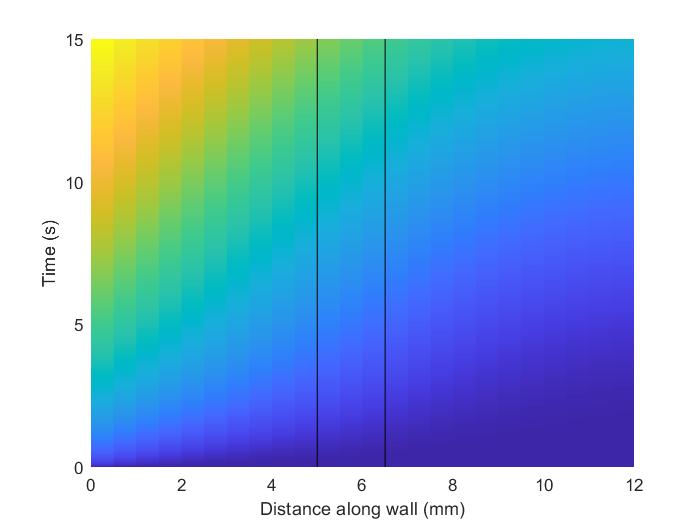

figure
surf(X,t,T,'LineStyle','none')
view(2)
xlabel('Distance along wall (mm)')
ylabel('Time (s)')
zlabel('Temperature (K)')
hold on
asd=Insulation_thickness+Air_thickness;
plot3([Insulation_thickness Insulation_thickness],[0 Sim_time],[2000 2000],'-black')
plot3([asd asd],[0 Sim_time],[2000 2000],'-black')
%[aaa,bbb]=meshgrid(Insulation_thickness.*ones(size(0:dx:Total_thickness)),0:dt:Sim_time);
%ccc=2000.*ones(size(aaa))
%surf(aaa,bbb,ccc)

hold off

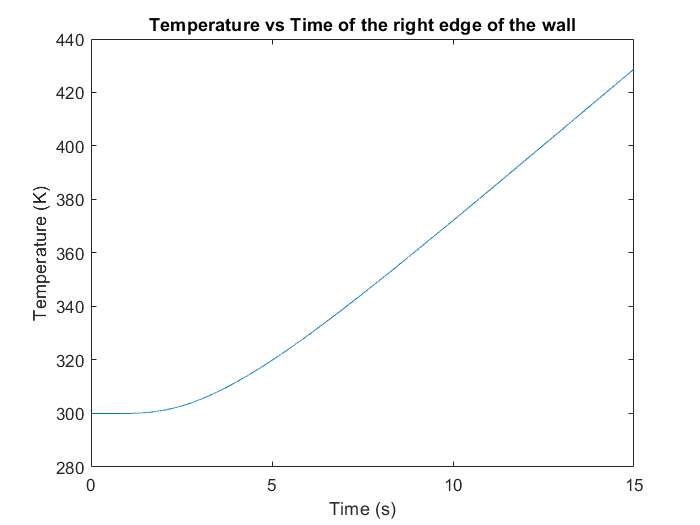


figure
plot(t(:,end),T(:,end))
xlabel('Time (s)')
ylabel('Temperature (K)')
title('Temperature vs Time of the right edge of the wall')

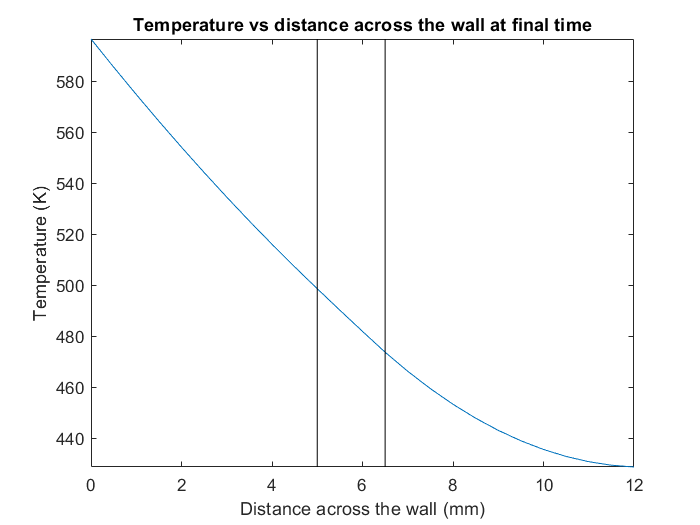


figure
plot(X(end,:),T(end,:))
xlabel('Distance across the wall (mm)')
ylabel('Temperature (K)')
title('Temperature vs distance across the wall at final time')

hold on
asd=Insulation_thickness+Air_thickness;
plot([Insulation_thickness Insulation_thickness],[0 2000],'-black')
plot([asd asd],[0 2000],'-black')
xlim([0 Total_thickness])
ylim([min(T(end,:)) max(T(end,:))])
hold off